# **P03: Funciones de Membresía**

## **Colaboradores**

- Fuentes Cendejas Héctor Tomás

## **Objetivos**

- Implementar operaciones de conjuntos difusos, utilizando MATLAB.

- Implementar transformaciones de conjuntos difusos, utilizando MATLAB.

## Introducción

En gran parte de los casos, es dificil clasificar los objetos del mundo real precisamente en un criterio específico de membresía. Si queremos clasificar a animales tales como perros, gatos, reptiles, aves, sabemos que podemos agregarles un valor de pertenencia a su determinado conjunto de manera total.

Pero, ¿que sucede con las estrellas de mar, bacterias, o cualquier ser vivo que pueda considerarse en más de una categoría debido a sus características? Estas situaciones las podemos encontrar en múltiples ocasiones de la vida diaria. En el caso de la ingeniería biónica, el objeto principal de estudio es el ser humano. 

A diferencia de las máquinas, las cuales toman decisiones tajantes basadas en ceros y unos (que en este caso tomamos como pertenencia o no pertenencia), la clave del acercamiento de los conjuntos difusos esta basada en la premisa de que, precisamente, el pensamiento humano dista de ser tajante, como el de las máquinas, para ser considerado como etiquetas de conjuntos difusos, en otras palabras, clases de objetos en donde la transición de pertenencia a no pertenencia es gradual en vez de abrupta. De hecho, el proceso del pensamiento humano sugiere que mucha de la lógica detrás del razonamiento esta basada en verdades difusas, conexiones difusas, y reglas difusas.

Con esto podemos dar por entendido la importancia de la lógica difusa como herramienta de la ingeniería.

## Problema 1 

**Investiga la expresión matemática para la función***** smf*** **y la función *****psigmf. *****Reporta dichas expresiones.**

### **Función smf**

La función *smf (S-shaped curve) *es una función que acepta valores, junto con parámetros con la siguiente sintaxis: smf(X,PARAMS)  y los introduce en la siguiente expresión matemática para después graficarla.

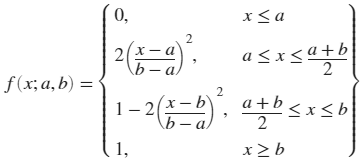

Como ejemplo tenemos el siguiente código

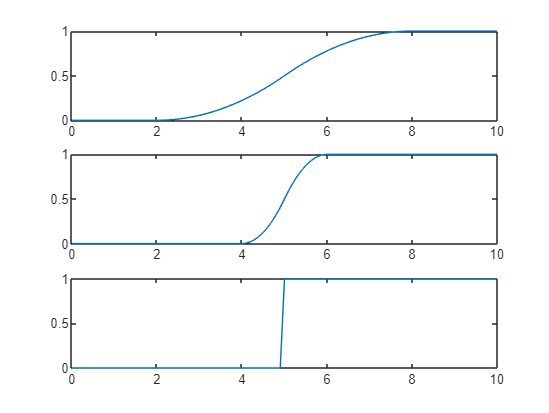

x = 0:0.1:10;
subplot(311); plot(x, smf(x,[2 8]));
subplot(312); plot(x, smf(x,[4 6]));
subplot(313); plot(x, smf(x,[6 4]));

### Función psigmf

La función *psigmf *es el prodcuto de dos funciones de membresía sigmoidales, la cual acepta también elementos y parámetros con la siguiente síntaxis: ***psigmf(X,PARAM)***. Cada función  sigmoidal tiene la siguiente expresión matemática:

 

En el siguiente código se generan dos funciones sigmoidales, para posteriormente ejecutar su producto por medio se la función referida

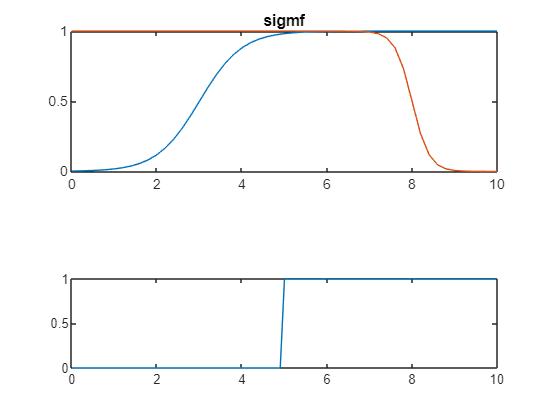


x = (0:0.2:10)';
params1 = [2 3];
y1 = sigmf(x, params1);
params2 = [-5 8];
y2 = sigmf(x, params2);
y3 = psigmf(x, [params1 params2]);
subplot(211);
plot(x, y1, x, y2); title('sigmf');

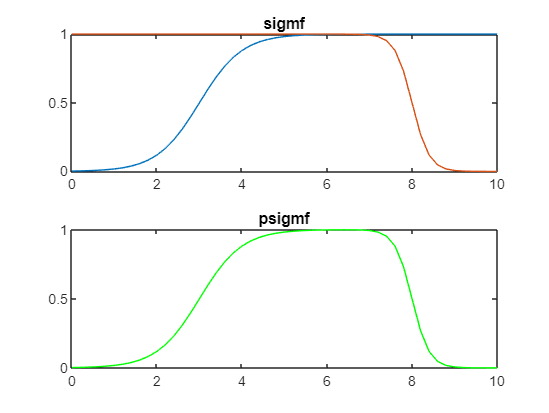

subplot(212);
plot(x, y3, 'g-'); title('psigmf');

## Problema 2

**Cree una función en MATLAB que reciba como argumentos de entrada el dominio y rango de una función de membresía**, **esta función debe crear la grafica del conjunto difuso con una edición de tu preferencia (no queremos repetir los códigos para gráficar cada vez que se quiera visualizar un conjunto difuzo, como se ha visto previamente).**

**Prueba el código con las dos funciones del problema anterior, los parámetros que debes utilizar  (debes investigar) son los que se usan en el ejemplo de la práctica. **

**Se espera esta sección dos llamadas a la función con las dos gráficas respectivas.**

x=0:0.2:10

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


y = smf(x,[2,3])

y =          0         0         0         0         0         0         0         0         0         0         0    0.0800    0.3200    0.6800    0.9200    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


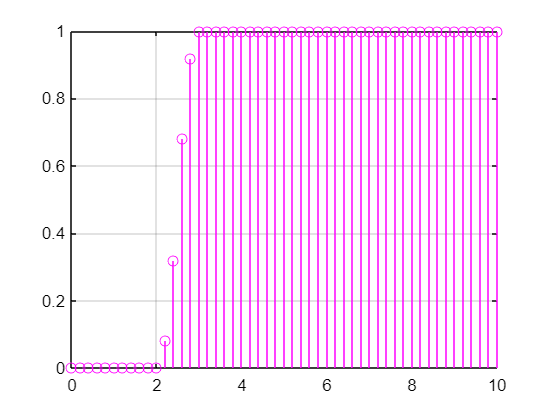

MFplotter(x,y)


x=0:0.2:10

x =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


y = psigmf(x,[2,3,-5,8])

y =     0.0025    0.0037    0.0055    0.0082    0.0121    0.0180    0.0266    0.0392    0.0573    0.0832    0.1192    0.1680    0.2315    0.3100    0.4013    0.5000    0.5987    0.6900    0.7685    0.8320    0.8808    0.9168    0.9427    0.9608    0.9734    0.9820    0.9879    0.9918    0.9945    0.9963    0.9975    0.9982    0.9986    0.9983    0.9970    0.9930    0.9818    0.9524    0.8807    0.7310    0.5000    0.2689    0.1192    0.0474    0.0180    0.0067    0.0025    0.0009    0.0003    0.0001


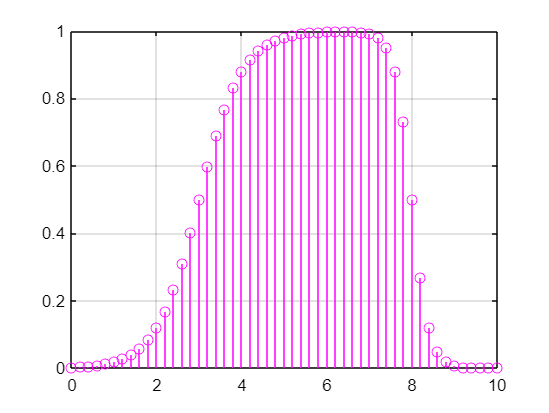

MFplotter(x,y)

## Problema 3

**Repite el problema anterior pero para conjuntos difusos en tiempo discreto.  **

**Prueba esta función con los conjuntos difusos (A, B) de la imagen 5 (OperDif5). de las notas *****NO2. Operaciones difusas que se encuentran en***** la página del curso.**

**Se espera esta sección dos llamadas a la función con las dos gráficas respectivas. **

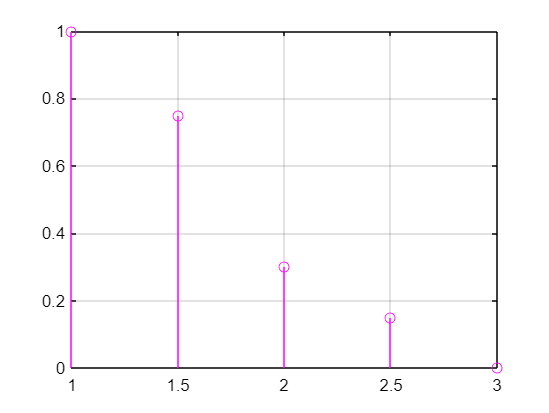

A = [1,1.5,2,2.5,3];
B = [1,1.5,2,2.5,3];
MFA = [1,0.75,0.3,0.15,0];
MFB = [1,0.6,0.2,0.1,0];

MFplotter(A,MFA);

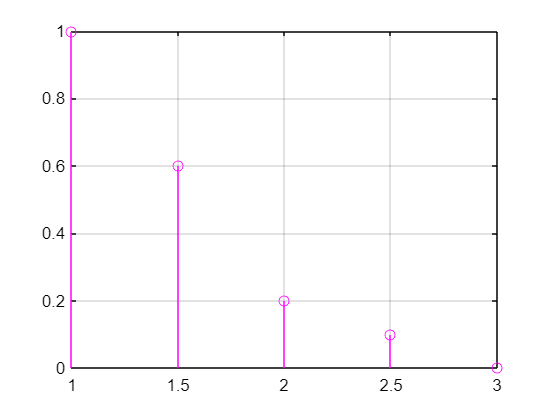

MFplotter(B,MFB);